# Fit Processed Data (Polynomial Fitting)

对filtered_final中的数据在去除前五个传感器数据后进行polynomial fitting (6th degree polynomial)。

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\processed data");
addpath(fpath,dpath);
load 'processed data'\filtered_final\tableStruct4.mat

第一步：去除前五个传感器的数据

for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    t(:,2:6) = []; %% 去除第2到第6列的数据
    tableStruct4(i).tableContents = t;

end

第二步：对剩下的数据进行polynomial fitting (6th degree polynomial)，并生成一个新表格储存重新确定的最大值及其位置（添加在结构数组的新字段栏目下）

x = 135:7.5:270; % polyfit的x轴（传感器位置）
minX = 135; maxX = 270; % 限制最大值对应的x的范围

for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    [num_rows, num_cols] = size(t);

    % 生成空白数组作为储存新最大值及其位置的表格的预备
    a = zeros(num_rows,2);

    % 生成空白数组作为储存RMSE的表格的预备
    b = zeros(num_rows,1);

    % 生成空白数组作为储存residual standard error的表格的预备
    c = zeros(num_rows,1);

    % 遍历表格t的每一行
    for j = 1:num_rows
        y = t{j, 2:end-2};  % 提取当前行的数据

        % 6次多项式拟合
        [p,S] = polyfit(x, y, 6);

        % 计算拟合值
        fitted_values = polyval(p,x);

        % 用拟合值替换原数据
        t{j, 2:end-2} = fitted_values;
        tableStruct4(i).tableContents = t;

       %% 确定拟合出的曲线的新最大值及其位置

        % 求导得到导数多项式
        dp = polyder(p);
    
        % 找出导数多项式的根，即找到极值点
        criticalPoints = roots(dp);
    
        % 过滤掉虚根，取实数部分
        criticalPoints = criticalPoints(imag(criticalPoints) == 0);
    
        % 过滤掉不在指定区间范围内的点
        criticalPoints = criticalPoints(criticalPoints >= minX & criticalPoints <= maxX);

        % 计算多项式在这些根上的值
        criticalValues = polyval(p,criticalPoints);

        % 如果没有在区间范围内的极值点，设置最大值和位置为NaN
        if isempty(criticalPoints)
            maxValue = NaN;
            maxLocation = NaN;
        else % 找到最大值和对应的位置       
            [maxValue, idx] = max(criticalValues);
            maxLocation = criticalPoints(idx);
        end

       %% 填入矩阵a
        a(j,1) = maxLocation; a(j,2) = maxValue;

       %% 将残差的L2范数转化为RMSE和RSE并分别填入向量b和c
        L2 = S.normr;
        RSS = L2^2; % residual sum of squares
        RMSE = sqrt(RSS / length(x));
        RSE = sqrt(RSS/(length(x)-6-1));
        b(j) = RMSE;
        c(j) = RSE;
    end

    % 用矩阵创造表格
    maxT_fitted = array2table(a, "VariableNames",["T_position","T_value"]);
    RMSE = array2table(b,"VariableNames","RMSE");
    RSE = array2table(c,"VariableNames","RSE");


    % 将表格存入新添加的字段 fitted_maxT
    tableStruct4(i).fitted_maxT = maxT_fitted;
    tableStruct4(i).RMSE = RMSE;
    tableStruct4(i).RSE = RSE;

end


tableStruct4 % saved as 'processed data'\polynomial_fitted\tableStruct_6th

tableStruct4 = 1×4 struct array with fields:
    tableName
    tableContents
    avgT_changeRate
    fitted_maxT
    RMSE
    RSE


tableStruct4(1).RMSE

ans = 345×1 table
     RMSE  
    _______

    0.12716
    0.12381
    0.11648
     0.1172
    0.13686
    0.11675
    0.11878
    0.10968
    0.11633
    0.11398
    0.11068
    0.12187
    0.13452
    0.12187
    0.11696
    0.11216


tableStruct4(1).RSE

ans = 345×1 table
      RSE  
    _______

    0.16001
    0.15579
    0.14657
    0.14747
    0.17221
    0.14691
    0.14946
      0.138
    0.14637
    0.14342
    0.13927
    0.15335
    0.16926
    0.15335
    0.14717
    0.14114


### 初步可视化验证

可视化最大值位置动画（使用被替代后的表格数据！所以最大值位置动画与精确情形有偏差！）

T_max position of data_10MPa_1.00h_Oil_20_deg_Stepped: 


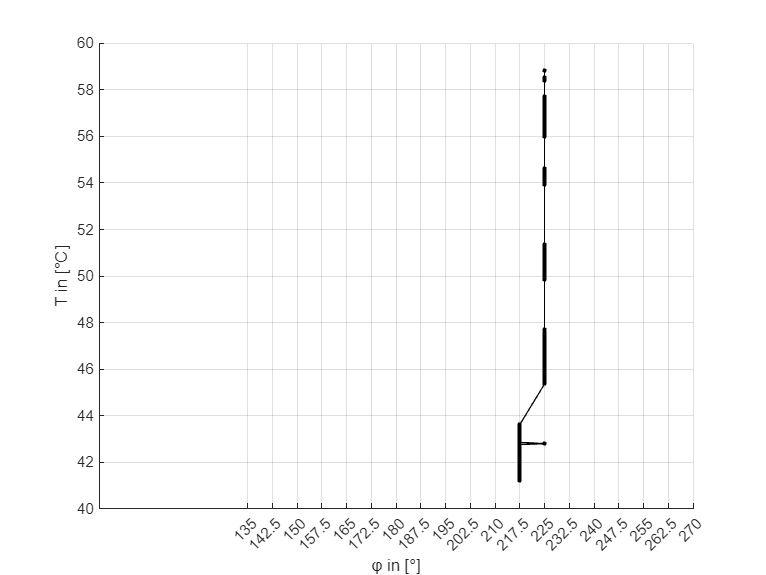

T_max position of data_10MPa_1.00h_Oil_60_deg_Stepped: 


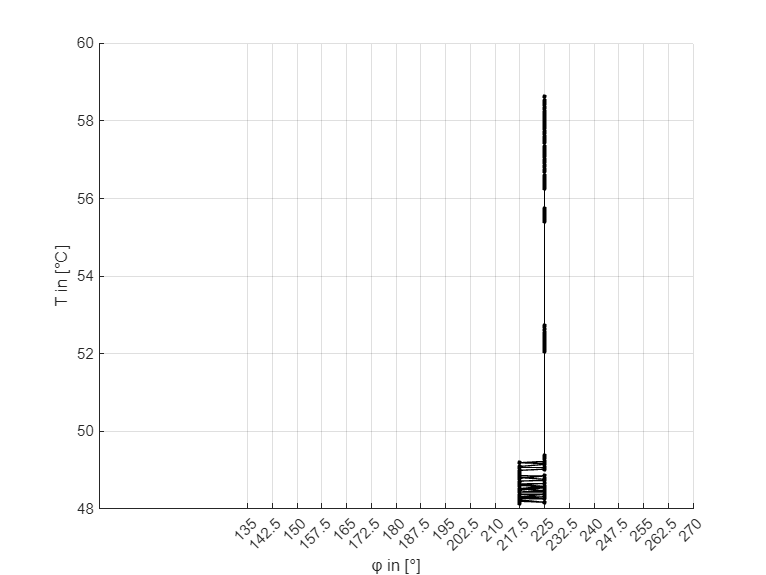

T_max position of data_15MPa_1.00h_Oil_60_deg_Stepped: 


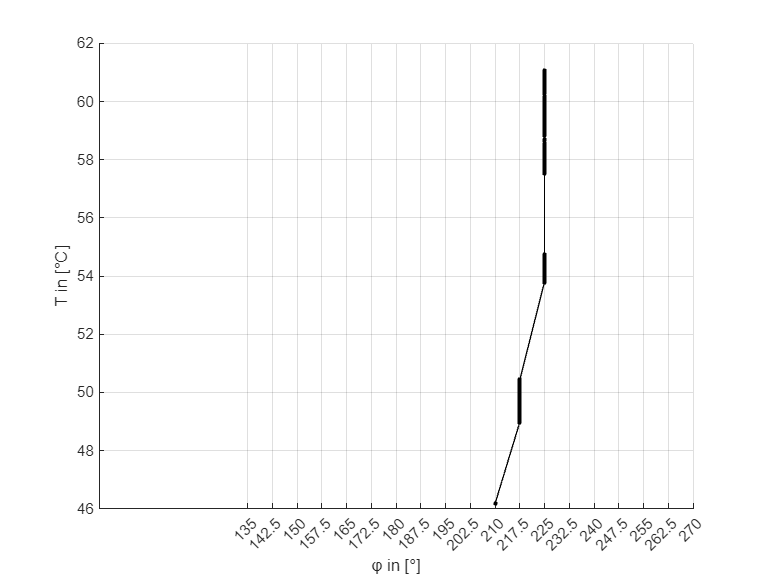

T_max position of data_15MPa_6xh_Oil_60_deg_Plateau_discontinued: 


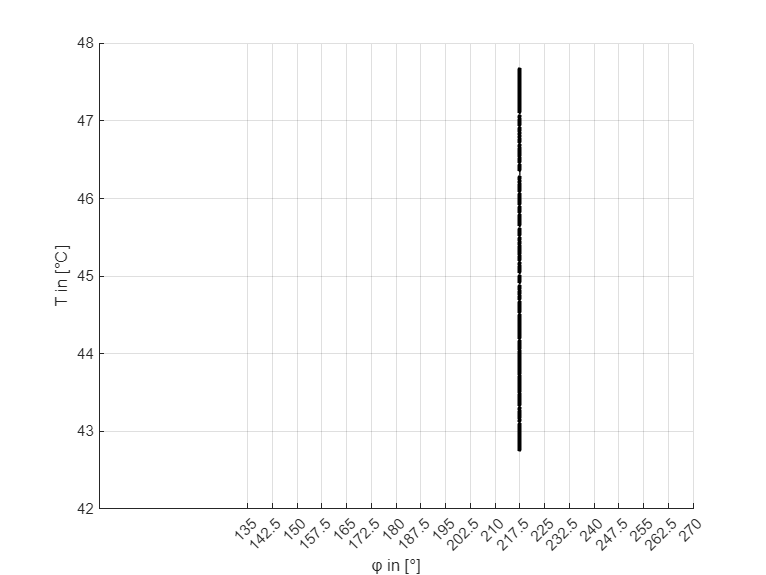

% 直接从这里开始
fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\processed data");
addpath(fpath,dpath);
load 'processed data'\polynomial_fitted\tableStruct4_6th.mat

sensor_position = 135:7.5:270; % 排除了前五个传感器

for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;

    %% 最大值位置动画（参照相关函数重新手写）
    maxT_position_animation(sensor_position,t);
end

Animation for data_10MPa_1.00h_Oil_20_deg_Stepped: 


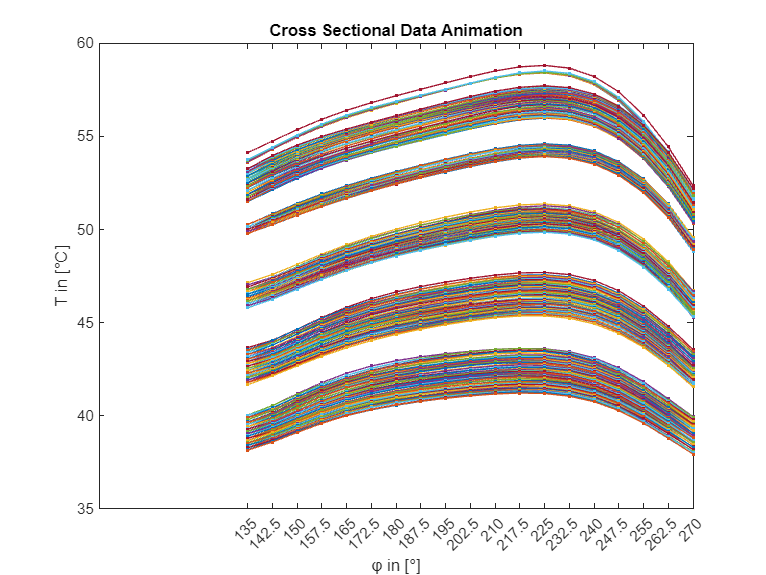

Animation for data_10MPa_1.00h_Oil_60_deg_Stepped: 


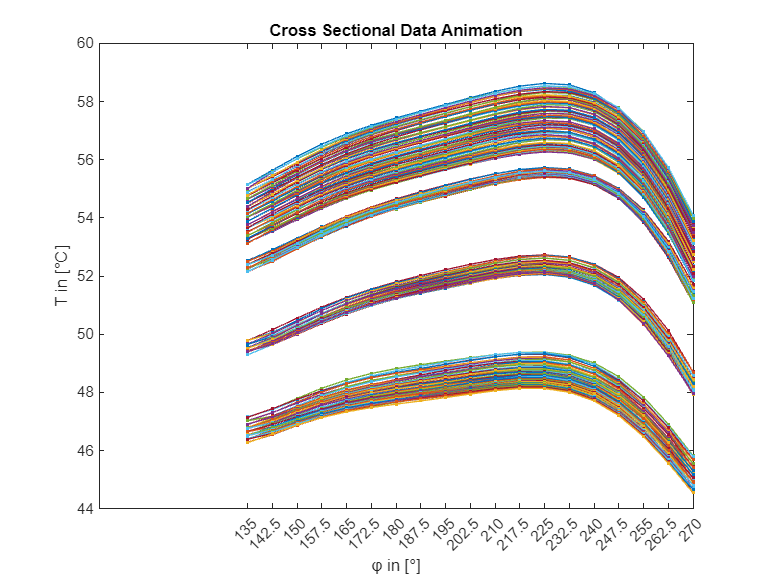

Animation for data_15MPa_1.00h_Oil_60_deg_Stepped: 


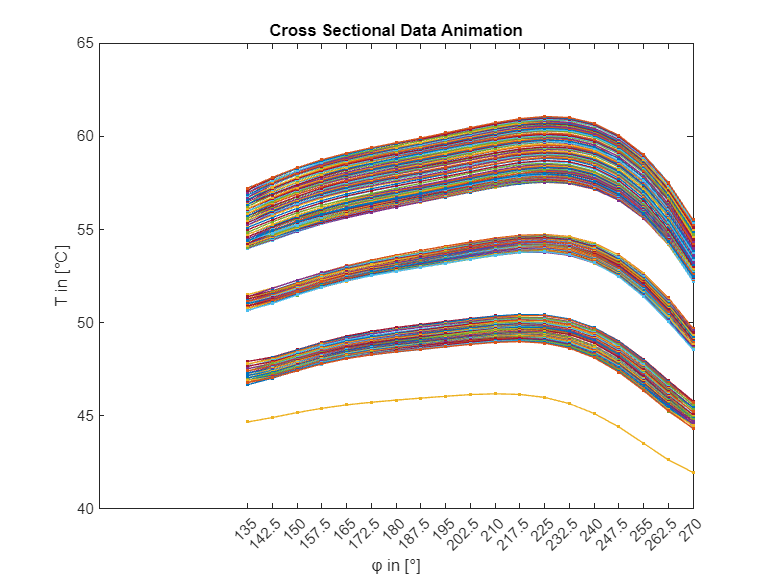

Animation for data_15MPa_6xh_Oil_60_deg_Plateau_discontinued: 


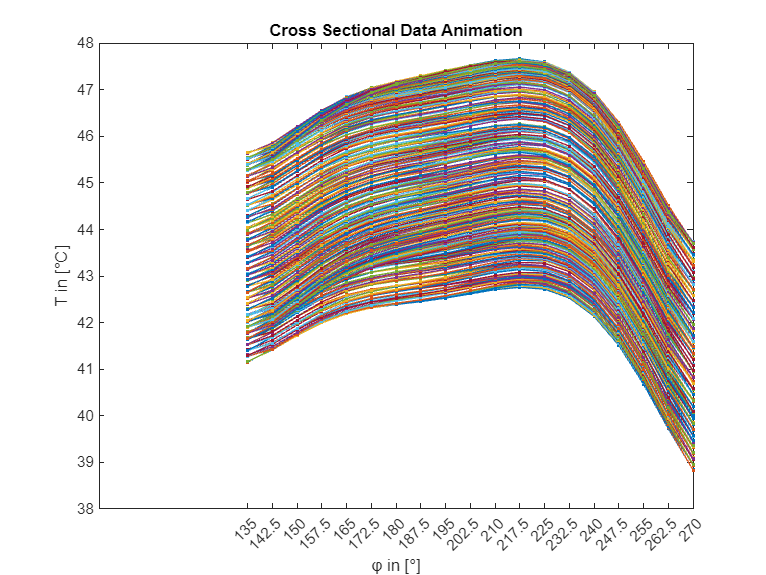

sensor_position = 135:7.5:270; % 排除了前五个传感器
for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents; 
    %% Test Plan 可视化
    %testplan_visualization(t); 

    %% 时间截面动画
    timeCrossSection_animation(sensor_position,t,1);
end